# **Machine Learning Model to Detect Types of Arrhythmia from the Features of  ECG Signal**

**Types of Arrhythmias**

There are two kinds of **trigeminy**:

- Two normal heartbeats followed by one extra beat

- One normal beat followed by two extra beats

**Ventricular tachycardia(VT**)  is a fast, abnormal heart rate. It starts in your heart's lower chambers, called the ventricles.

If the heart is skipping a beat or having rapid beats.**(****Bigeminy****)**

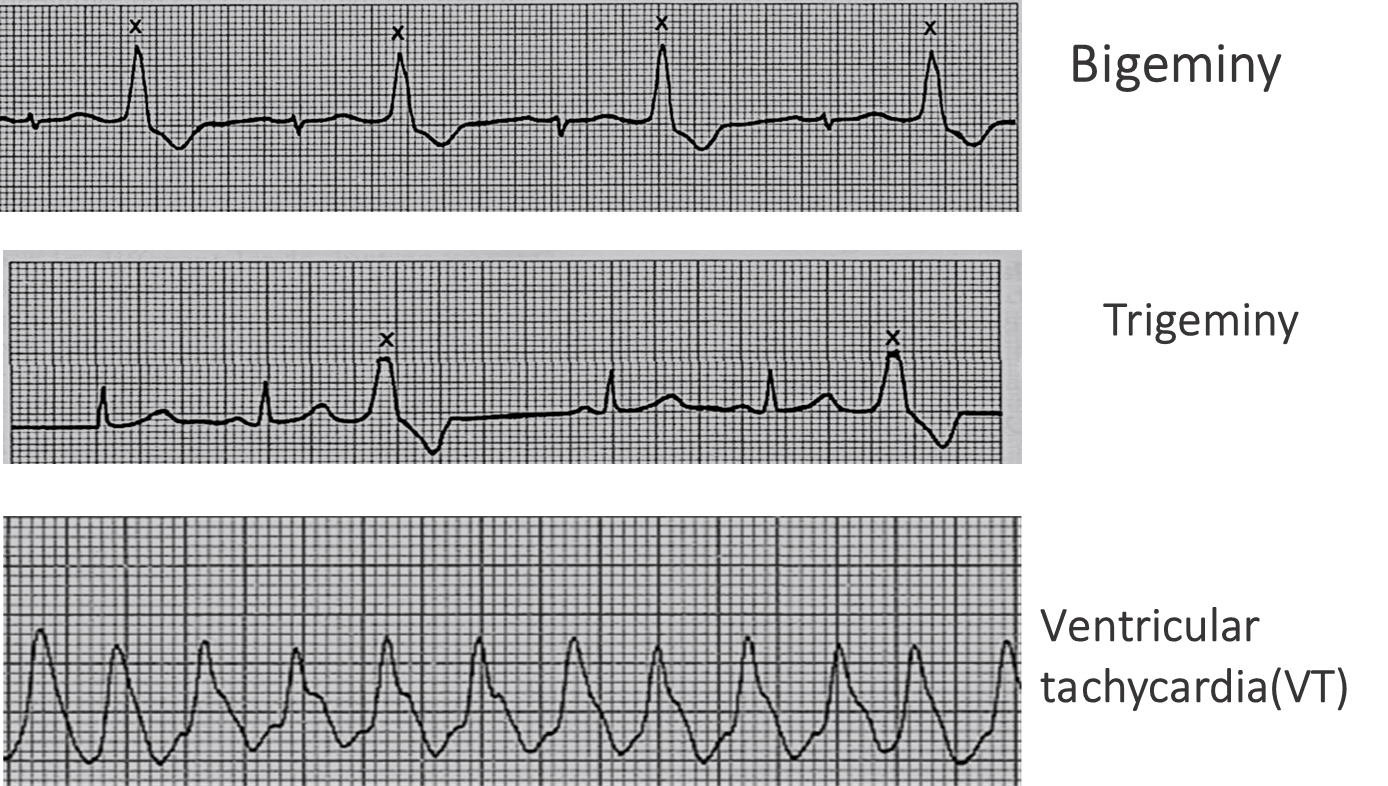

## **Features**

**Amplitude (in mv) **Height of R wave

**RR  **The R-R interval: The RR interval is the time between QRS complexes. (normal is between (0.6 to 1 second)

**Speed **For adults 18 and older, a normal resting heart rate is between 60 and 100

**Age **23/89

**Gender  **M/F

Dataset [https://github.com/davikawasaki/arrhythmia-ecg-analysis-ai](https://github.com/davikawasaki/arrhythmia-ecg-analysis-ai)

## Load Data

TrainData=readtable('samples-training.xlsx');
TestData=readtable('samples-testing.xlsx');
TrainData.Gender=categorical(TrainData.Gender);
TrainData.Arrhythmia=categorical(TrainData.Arrhythmia);
TestData.Gender=categorical(TestData.Gender);
TestData.Arrhythmia=categorical(TestData.Arrhythmia);

## Summary of Data

summary(TrainData)

Variables:

    Amplitude: 2931×1 double

        Values:

            Min         0.52  
            Median      0.96  
            Max         2.31  

    RR: 2931×1 double

        Values:

            Min         0.38  
            Median      0.81  
            Max         2.53  

    Speed: 2931×1 double

        Values:

            Min         0.31  
            Median      1.19  
            Max         5.85  

    Age: 2931×1 double

        Values:

            Min        23.00  
            Median     69.00  
            Max        89.00  

    Gender: 2931×1 categorical

        Values:

            F     627.00 
            M    2304.00 

    Arrhythmia: 2931×1 categorical

        Values:

            (B       42.00 
            (N     2819.00 
            (T       39.00 
            (VT      31.00 



summary(TestData)

Variables:

    Amplitude: 741×1 double

        Values:

            Min         0.51  
            Median      1.31  
            Max         1.94  

    RR: 741×1 double

        Values:

            Min         0.56  
            Median      0.97  
            Max         2.55  

    Speed: 741×1 double

        Values:

            Min         0.22  
            Median      1.35  
            Max         2.73  

    Age: 741×1 double

        Values:

            Min        23.00  
            Median     75.00  
            Max        89.00  

    Gender: 741×1 categorical

        Values:

            F     730.00 
            M      11.00 

    Arrhythmia: 741×1 categorical

        Values:

            (B       12.00 
            (N      707.00 
            (T       12.00 
            (VT      10.00 



## **Histogram of Age, Gender and Types of  Arrhythmias of Training Data**

**Histogram of age**

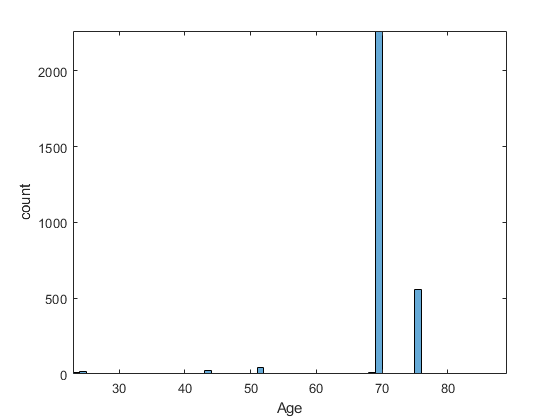

histogram(TrainData.Age) 
axis tight 
xlabel('Age')
ylabel('count')

**Histogram of M/F**

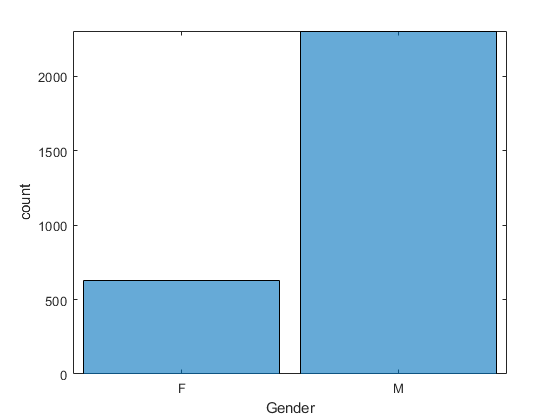

histogram(TrainData.Gender) 
axis tight 
xlabel('Gender')
ylabel('count')

**Histogram of Arrhythmias**

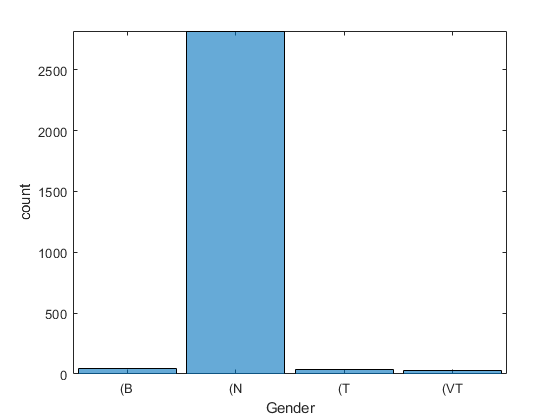

histogram(TrainData.Arrhythmia) 
axis tight 
xlabel('Gender')
ylabel('count')

## **Histogram of Age, Gender and Types of  Arrhythmias of Testing Data**

**Histogram of age**

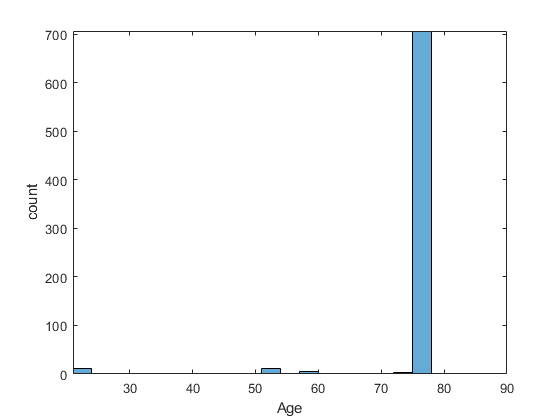

histogram(TestData.Age) 
axis tight 
xlabel('Age')
ylabel('count')

**Histogram of M/F**

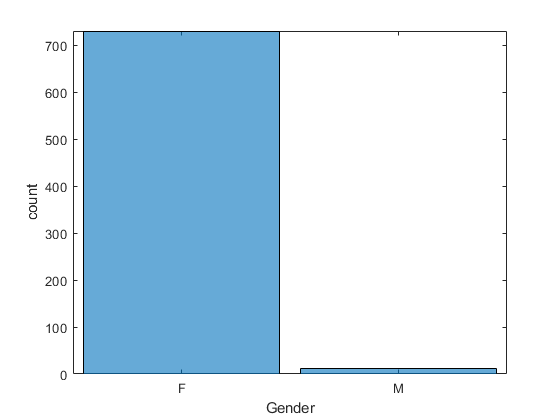

histogram(TestData.Gender) 
axis tight 
xlabel('Gender')
ylabel('count')

**Histogram of Arrhythmias**

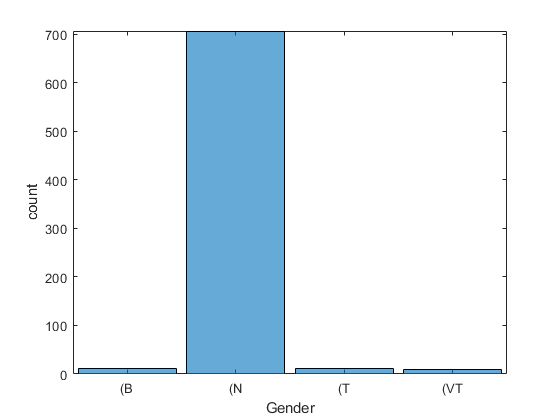

histogram(TestData.Arrhythmia) 
axis tight 
xlabel('Gender')
ylabel('count')

## **Create Model**

classificationLearner

trainedModel = trainClassifier(TrainData);


## Visualize the Training Accuracy

trainPred=trainedModel.predictFcn (TrainData(:,1:5));

Accuracy

MLAccuracytrain = sum(trainPred == TrainData.Arrhythmia)/numel(trainPred)*100

MLAccuracytrain =          99.35


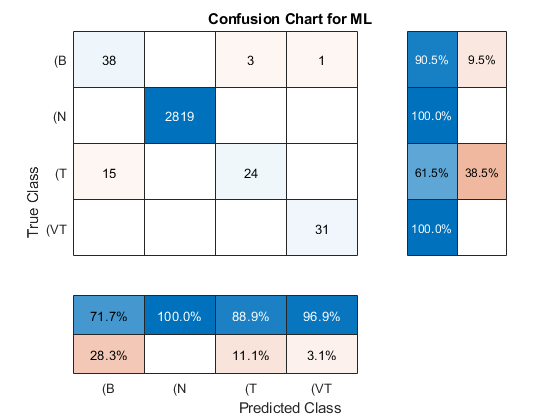

figure
confusionchart(TrainData.Arrhythmia,trainPred,'ColumnSummary','column-normalized',...
              'RowSummary','row-normalized','Title','Confusion Chart for ML');

##  Viisulize the Testing Accuracy

testPred=trainedModel.predictFcn (TestData(:,1:5));

Accuracy

MLAccuracytest = sum(testPred == TestData.Arrhythmia)/numel(testPred)*100

MLAccuracytest =          97.84


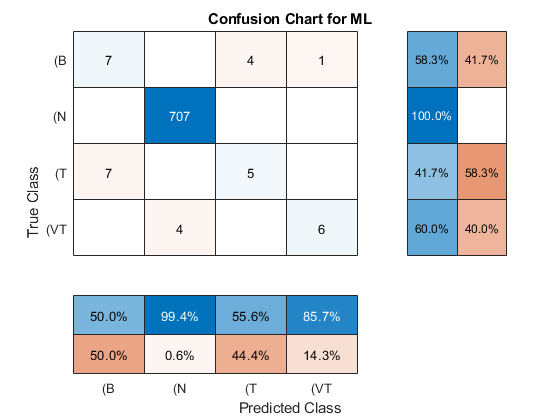

figure
confusionchart(TrainData.Arrhythmia,testPred,'ColumnSummary','column-normalized',...
              'RowSummary','row-normalized','Title','Confusion Chart for ML');

function [trainedClassifier, validationAccuracy] = trainClassifier(trainingData)
% [trainedClassifier, validationAccuracy] = trainClassifier(trainingData)
% Returns a trained classifier and its accuracy. This code recreates the
% classification model trained in Classification Learner app. Use the
% generated code to automate training the same model with new data, or to
% learn how to programmatically train models.
%
%  Input:
%      trainingData: A table containing the same predictor and response
%       columns as those imported into the app.
%
%  Output:
%      trainedClassifier: A struct containing the trained classifier. The
%       struct contains various fields with information about the trained
%       classifier.
%
%      trainedClassifier.predictFcn: A function to make predictions on new
%       data.
%
%      validationAccuracy: A double containing the accuracy in percent. In
%       the app, the History list displays this overall accuracy score for
%       each model.
%
% Use the code to train the model with new data. To retrain your
% classifier, call the function from the command line with your original
% data or new data as the input argument trainingData.
%
% For example, to retrain a classifier trained with the original data set
% T, enter:
%   [trainedClassifier, validationAccuracy] = trainClassifier(T)
%
% To make predictions with the returned 'trainedClassifier' on new data T2,
% use
%   yfit = trainedClassifier.predictFcn(T2)
%
% T2 must be a table containing at least the same predictor columns as used
% during training. For details, enter:
%   trainedClassifier.HowToPredict

% Auto-generated by MATLAB on 31-May-2020 23:30:38


% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable = trainingData;
predictorNames = {'Amplitude', 'RR', 'Speed', 'Age', 'Gender'};
predictors = inputTable(:, predictorNames);
response = inputTable.Arrhythmia;
isCategoricalPredictor = [false, false, false, false, true];

% Train a classifier
% This code specifies all the classifier options and trains the classifier.
classificationTree = fitctree(...
    predictors, ...
    response, ...
    'SplitCriterion', 'gdi', ...
    'MaxNumSplits', 4, ...
    'Surrogate', 'off', ...
    'ClassNames', categorical({'(B'; '(N'; '(T'; '(VT'}));

% Create the result struct with predict function
predictorExtractionFcn = @(t) t(:, predictorNames);
treePredictFcn = @(x) predict(classificationTree, x);
trainedClassifier.predictFcn = @(x) treePredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
trainedClassifier.RequiredVariables = {'Age', 'Amplitude', 'Gender', 'RR', 'Speed'};
trainedClassifier.ClassificationTree = classificationTree;
trainedClassifier.About = 'This struct is a trained model exported from Classification Learner R2020a.';
trainedClassifier.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');

% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable = trainingData;
predictorNames = {'Amplitude', 'RR', 'Speed', 'Age', 'Gender'};
predictors = inputTable(:, predictorNames);
response = inputTable.Arrhythmia;
isCategoricalPredictor = [false, false, false, false, true];

% Perform cross-validation
partitionedModel = crossval(trainedClassifier.ClassificationTree, 'KFold', 5);

% Compute validation predictions
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);

% Compute validation accuracy
validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');
end